# Frequency responses with MATLAB

This file serves two purposes. First it gives illustrations of what frequency response means in terms of the time domain behaviour of a system. Second, it shows how MATLAB code can be deployed to analyse frequency response and compute/display important values. Users can modify the systems definitions in the code to be of their choice, but doing this they may also need to modify some of the default selections such as simulation time or frequency.

This live script needs the control toolbox and also the subfunction ds2nfu.m (see bottom) used to support the figure annotation.

Users might also like to see  the app: ***frequency_response_time_behaviour.mlapp*** which is part of the toolbox and automates much of the illustrations shown in the code below.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical background

- Response of a system to a sinusoidal input 

- Identifying the  gain and phase from the figure

- Warnings

- Precise computations

- ***frequency_response_time_behaviour.mlapp***

- Subfunction dsnfu.m

## 1. Technical background

Frequency responses are a type of behaviour that can be very useful in feedback design. However, before we move to that, we need to focus on: what is frequency response?

Consider you have a system G(s) with input u(s) and output y(s).  What would the **asymptotic** output y(t) be if u(t) = sin (wt)?


$$Y\left(s\right)=G\left(s\right)U\left(s\right);\;\;u\left(t\right)=\sin \left(\omega t\right)\;\Longrightarrow \;y\left(t\right)=\textrm{Asin}\left(\omega t+\phi \right)+B$$


It can be shown that the gain parameter A and phase parameter $\phi$ are dependent on frequency $\omega$. Frequency response describes the implied relationships:


$$A=A\left(\omega \right);\;\;\phi =\phi \left(\omega \right)$$


The ***lsim.m*** function in MATLAB assumes that the system is represented by a linear model (typically transfer function or state space) and allows the input to be time varying (e.g. a sinusoid) and will be used below to illustrate frequency response in the time domain. Specifically the user will note how the gain and phase parameters change as the input frequency changes; computations of A and $\phi$ displayed at the end of section 2.

## 2. Response of a system to a sinusoidal input 

This section demonstrates the computation and display of the system response to a sinusoidal input. 

**Users can change the system model and input frequency by editing the lines 2-3 below. NOTE that the time scale  is chosen automatically based on the slowest time constant of G(s) and should be  fast enough so that any transient behaviour has sufficiently decayed. **

**CORE TASK: For the same G, change the frequency (for example try **$\omega$**=1,2,3), use "run section",  and note from the figure how  the behaviour,  gain and phase parameters change (precise numeric values given in section 3).**

NOTE: For clarity of presentation in the figure, it would be wise to ensure the gain of G(s) is similar to one. If the magnitude of the input and output plots are mismatched, modify the gain of G(s) appropriately.

% data entry
G = tf([1 0.3],[1 0.8 0.4]) %%% Create  linear system 

G =
 
       s + 0.3
  -----------------
  s^2 + 0.8 s + 0.4
 
Continuous-time transfer function.
Model Properties


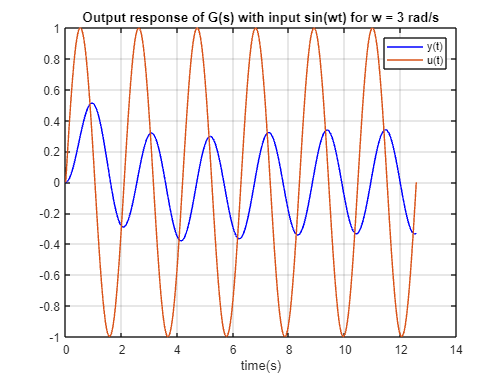

omega = 3;                  %%% define the input frequency in rad/s

%%% Choose a sensible simulation time
p=pzmap(G); pslow = max(real(p));  %%% find slowest pole
if pslow ~=0;mintime = 5/abs(pslow); else;mintime=20;end   %% minimum simulation time to get past transients
singleperiod  = 2*pi/omega;   %% time for a single period of the signal
nperiods = ceil(mintime/singleperiod);  %% minimum number of periods
if nperiods ==1;nperiods =2;end
time = nperiods*singleperiod;  %%% proposed simulation time
tvec = linspace(0,time,80*nperiods);  %% vector of time instants for the plot

%computation and plotting
u=sin(omega*tvec);     %%% input signal
y=lsim(G,u,tvec);
figure ;clf;
plot(tvec,y,'b',tvec,u);grid;hold on
title(['Output response of G(s) with input sin(wt) for w = ',num2str(omega),' rad/s'])
xlabel('time(s)')
legend('y(t)','u(t)')

The core observations are that after the transients have decayed,  it is seen that the output is sinusoidal with the same frequency of the input signal, but with a phase shift and a different amplitude which depend on the frequency.

## 3. Identifying the  gain and phase from the figure

The values for the gain and phase can be estimated from the figure but to get reasonable accuracy one would want to zoom in on the detail. The phase difference $\phi$ is equivalent to a time difference, that is in  simple terms:


$$\varphi =\omega \left(\textrm{t1}-\textrm{t2}\right)$$


where t1 and t2 are the corresponding times on the input and output responses.

This section demonstrates such a zoom using **a simply chosen** time period to identify t1 and t2. We select a period where any transients (see section 3) are expected to have decayed.

- The left figure zooms on the input to capture the time for a peak as  t1.

- The right hand zooms on the output so we can capture the time for a corresponding peak as t2.

The magnitude A is half peak to peak of the output (see double sided arrow in the right hand figure).

**Note that  the notation/arrows in this window assume that the user has not changed the definition of time in line 11.  The code below is not intended for the user to edit unless they know what they are doing!**

disp('BELOW is SECTION 3')

BELOW is SECTION 3



% computer zoom parameters for the plots
lefttime=(nperiods-1)*80;arrowtime=(nperiods-0.75)*80;
righttime=nperiods*80; mid = (nperiods-0.2)*80;
pts = lefttime:righttime;
ymax = max(y(pts)); ymin = min(y(pts));
[mag,phase]=bode(G,omega);
shift = phase*pi/(omega(:)*180);

%% Display of core numerical answers
disp(['The magnitude A is ',num2str((ymax-ymin)/2)]);

The magnitude A is 0.11244


disp(['The input peak is at t1 = ',num2str(tvec(arrowtime))])

The input peak is at t1 = 19.3712


disp(['The corresponding output peak is at t2 = ',num2str(tvec(arrowtime)-shift)])

The corresponding output peak is at t2 = 20.3609


disp(['The corresponding phase (deg) is at (t1 - t2)/w = ',num2str(phase)])

The corresponding phase (deg) is at (t1 - t2)/w = -170.1178


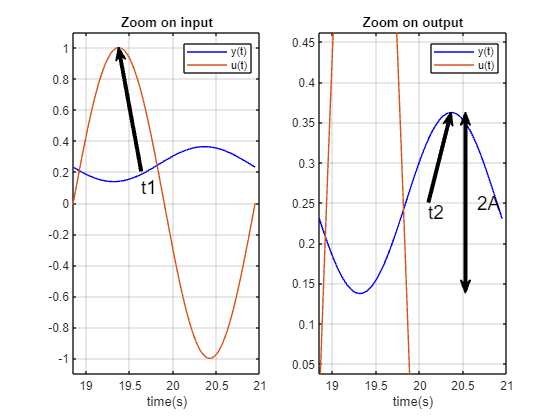


%% zoomed figure on the input
figure;clf
subplot(121)
plot(tvec(pts),y(pts),'b',tvec(pts),u(pts));grid;
title('Zoom on input')
xlabel('time(s)')
legend('y(t)','u(t)')
ylim([-1.1,1.1]);
%%% annotations for left hand figure
[Xf, Yf] = ds2nfu([tvec(arrowtime+10),tvec(arrowtime)], [0.2,1]);
annotation('arrow',Xf,Yf,'linewidth',3);
text(tvec(arrowtime+10),0.1,'t1','fontsize',14)

%% zoomed figure on the output
subplot(122)
plot(tvec(pts),y(pts),'b',tvec(pts),u(pts));grid; hold on
ylim([ymin-0.1,ymax+0.1])
xlabel('time(s)')
legend('y(t)','u(t)')
title('Zoom on output')
%%% annotations for right hand figure
[Xf, Yf] = ds2nfu([tvec(mid),tvec(mid)], [ymin,ymax]);
annotation('doublearrow',Xf,Yf,'linewidth',3);
text(tvec(mid+5),(ymax+ymin)/2,'2A','fontsize',14)
[Xf, Yf] = ds2nfu([tvec(arrowtime-10)-shift,tvec(arrowtime)-shift], [(ymax+ymin)/2,ymax]);
annotation('arrow',Xf,Yf,'linewidth',3);
text(tvec(arrowtime-10)-shift,(0.45*ymax+0.55*ymin),'t2','fontsize',14)

## 4. Warnings 

The response of a system will always include transients so it is important to ensure these transients have died down before estimating the gain and phase parameters. The figures here illustrate some examples where the transient behaviour is evident and not fully decayed at the end time.

Integrators will cause the output to oscillate around a non-zero value. You can try that by changing G2 or G3 below.

You could increase the end time (equivalently definition of *variable tvec2*) and you will see that the responses will settle to the asymptotic sinusoid eventually.

disp('BELOW is SECTION 4: Warnings')

BELOW is SECTION 4: Warnings


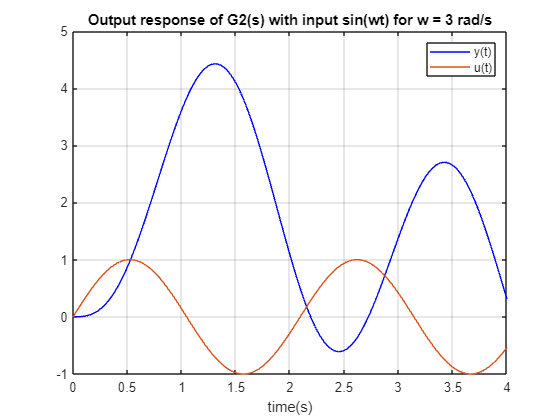


G2 = tf(20,[1 2 1]);
%G2 = tf(1,[1 2 0]); with integrator
tvec2 = linspace(0,4,1000);
u2=sin(3*tvec2);     %%% input signal
y2=lsim(G2,u2,tvec2);
figure ;clf;
plot(tvec2,y2,'b',tvec2,u2);grid;hold on
title(['Output response of G2(s) with input sin(wt) for w = 3 rad/s'])
xlabel('time(s)')
legend('y(t)','u(t)')

See how response is still in transients, so we cannot use this to estimate gain and phase.

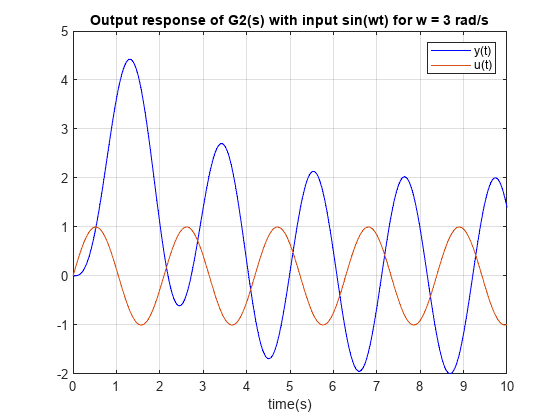

tvec2 = linspace(0,10,1000);
u2=sin(3*tvec2);     %%% input signal
y2=lsim(G2,u2,tvec2);
figure ;clf;
plot(tvec2,y2,'b',tvec2,u2);grid;hold on
title(['Output response of G2(s) with input sin(wt) for w = 3 rad/s'])
xlabel('time(s)')
legend('y(t)','u(t)')

See how response is still in transients, so we cannot use this to estimate gain and phase.

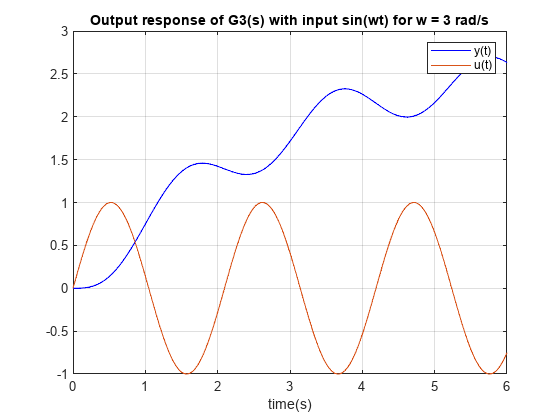


G3 = tf(2.5,[1 0.2 0.03]);
tvec3 = linspace(0,6,1000);
u3=sin(3*tvec3);     %%% input signal
y3=lsim(G3,u3,tvec3);
figure ;clf;
plot(tvec3,y3,'b',tvec3,u3);grid;hold on
title(['Output response of G3(s) with input sin(wt) for w = 3 rad/s'])
xlabel('time(s)')
legend('y(t)','u(t)')

See how response is still in transients, so we cannot use this to estimate gain and phase.

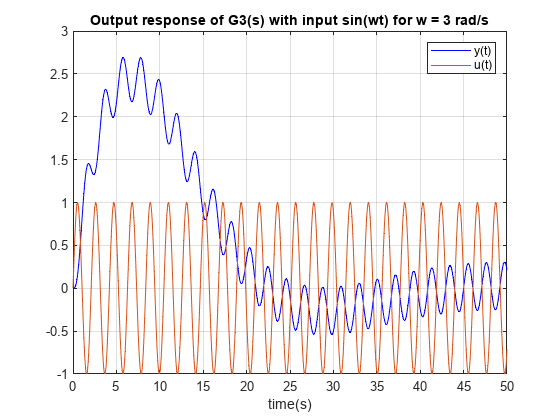

tvec3 = linspace(0,50,1000);
u3=sin(3*tvec3);     %%% input signal
y3=lsim(G3,u3,tvec3);
figure ;clf;
plot(tvec3,y3,'b',tvec3,u3);grid;hold on
title(['Output response of G3(s) with input sin(wt) for w = 3 rad/s'])
xlabel('time(s)')
legend('y(t)','u(t)')

See how response is still in transients, so we cannot use this to estimate gain and phase.

## 5. Precise computations 

One can determine precise values for gain and phase using suitable algebra and without recourse to the time domain plots. Explanation is elsewhere and here we simply summarise the appropriate matlab command which is *bode.m*

Find the gain and phase (in degrees) for a single frequency using:

disp('BELOW is SECTION 5')

BELOW is SECTION 5



disp('Gain and phase for a single frequency')

Gain and phase for a single frequency


omega = 1;
G3 = tf(0.5,[1 0.2 0.03]);
[A,phi]= bode(G3,omega)

A = 0.5048

phi = -168.3497

Find the gain and phase (in degrees) for a multiple frequencies using:

disp('Gain and phase for multiple frequencies at once')

Gain and phase for multiple frequencies at once


omegalist = [0.6:0.1:1];
[A,phi]= bode(G3,omegalist)

A = A(:,:,1) =

    1.4239


A(:,:,2) =

    1.0399


A(:,:,3) =

    0.7929


A(:,:,4) =

    0.6246


A(:,:,5) =

    0.5048


phi = phi(:,:,1) =

 -160.0169


phi(:,:,2) =

 -163.0725


phi(:,:,3) =

 -165.3027


phi(:,:,4) =

 -167.0054


phi(:,:,5) =

 -168.3497


You will note that the syntax for the output variables is somewhat cumbersome, especially for a large number of frequencies, but this can be simplified if desired using commands such as:

disp('Gain and phase for multiple frequencies at once - neater display')

Gain and phase for multiple frequencies at once - neater display


A2=A(:)'

A2 =     1.4239    1.0399    0.7929    0.6246    0.5048


phi2 = phi(:)'

phi2 =  -160.0169 -163.0725 -165.3027 -167.0054 -168.3497


For completeness we also show that a plot of these values can be produced using a different call statement with *bode.m* (no output arguments); note the gain plot is translated to decibels. More on this in later files.

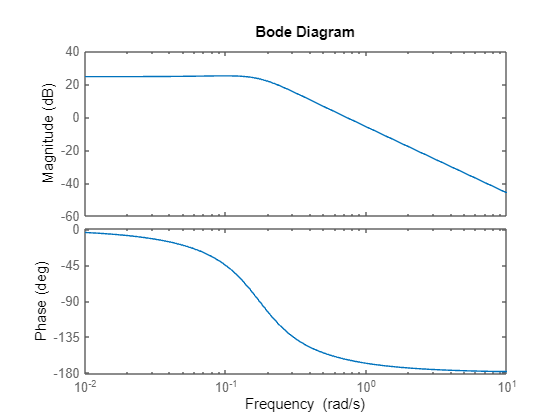

bode(G3)

## 6. ***frequency_response_time_behaviour.mlapp***

A screen dump of the app is given here. This file is part of the control101 toolbox so should appear under the apps tab once you have downloaded the toolbox.

% frequency_response_time_behaviour

The purpose of the app is to allow users to focus on concepts and learning rather than coding, whereas this livescript gives more focus on the mathematical and coding details.

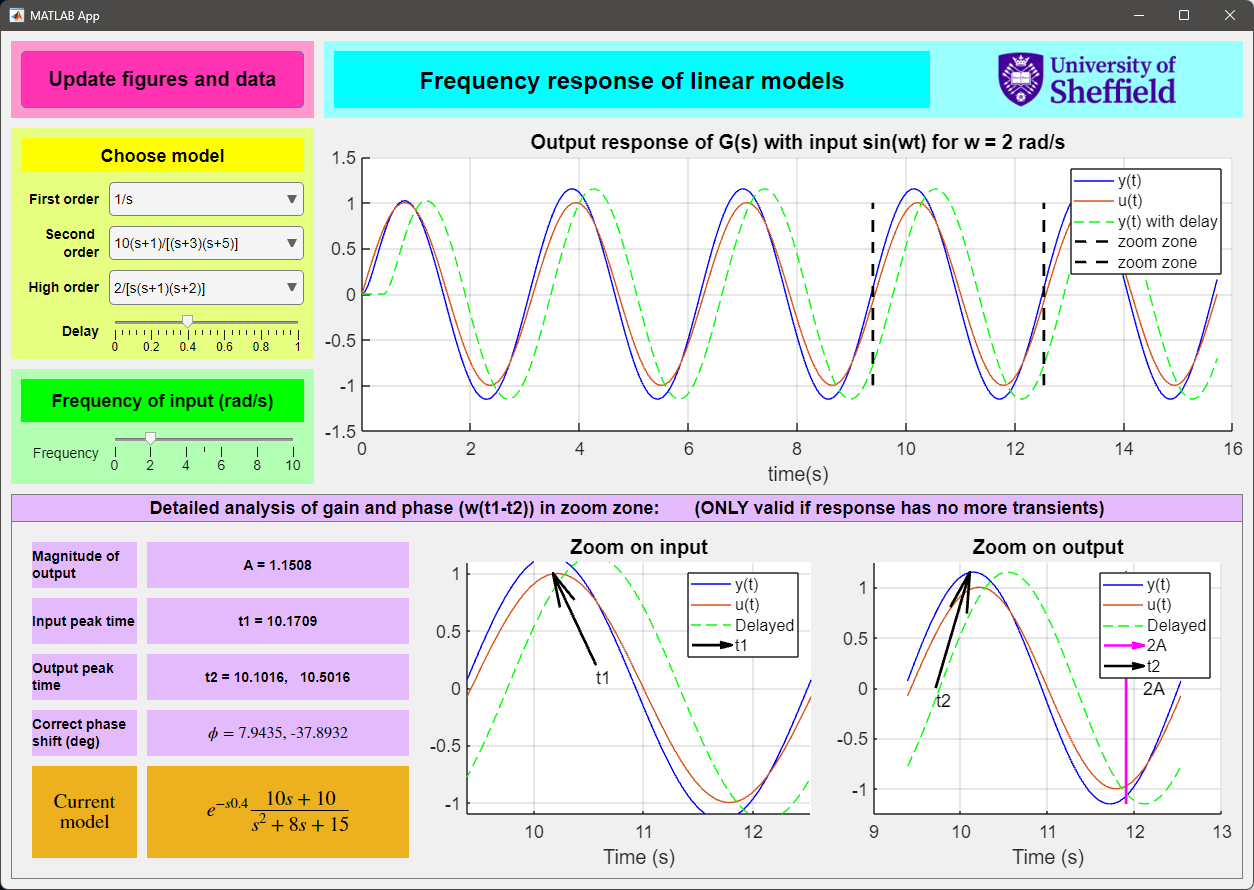

## 6. Subfunction dsnfu.m ( mhirsch@mathworks.com,  Copyright 2006-2014, The MathWorks, Inc)

Opening existing copy - delete or rename this copy to access toolbox orginal


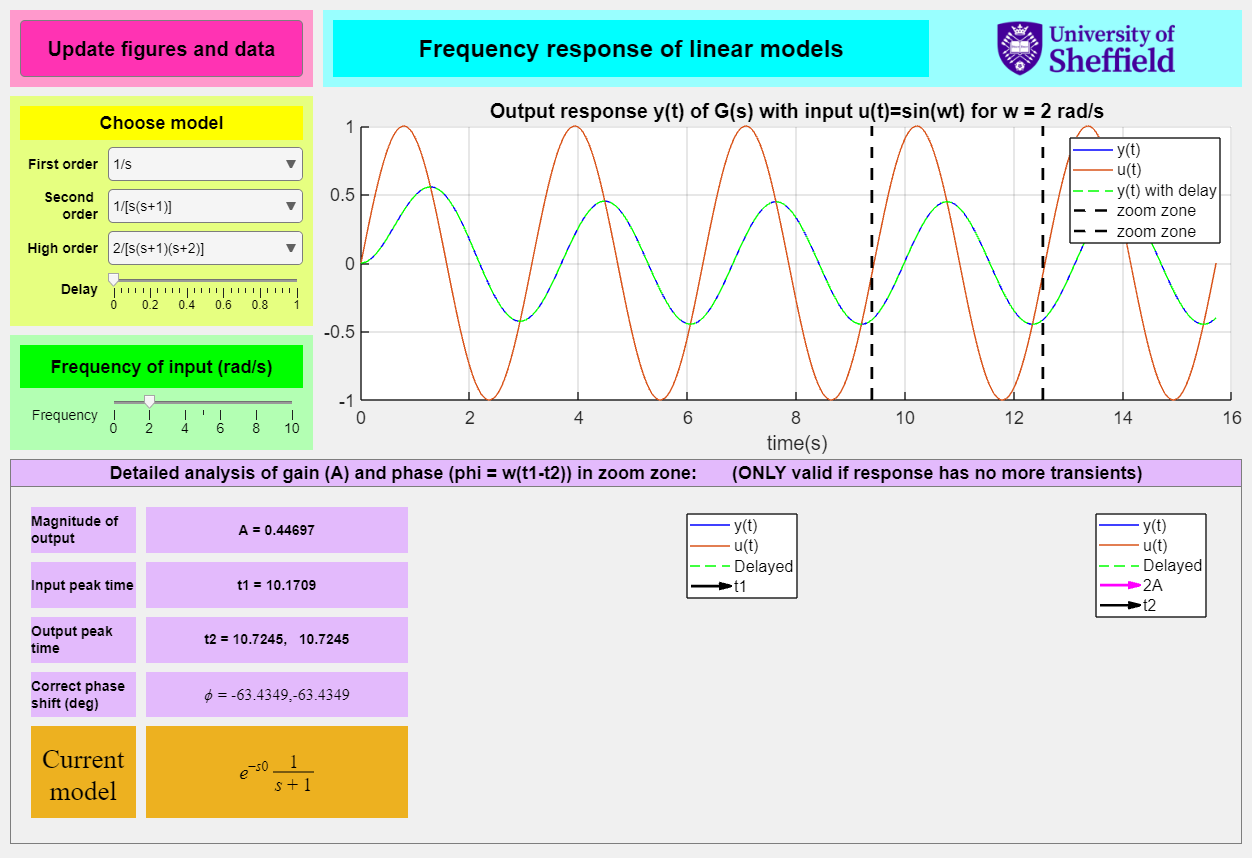

function varargout = ds2nfu(varargin)

% DS2NFU  Convert data space units into normalized figure units. 
%
% [Xf, Yf] = DS2NFU(X, Y) converts X,Y coordinates from
% data space to normalized figure units, using the current axes.  This is
% useful as input for ANNOTATION.  
%
% POSf = DS2NFU(POS) converts 4-element position vector, POS from
% data space to normalized figure units, using the current axes.  The
% position vector has the form [Xo Yo Width Height], as defined here:
%
%      web(['jar:file:D:/Applications/MATLAB/R2006a/help/techdoc/' ...
%           'help.jar!/creating_plots/axes_pr4.html'], '-helpbrowser')
%
% [Xf, Yf] = DS2NFU(HAX, X, Y) converts X,Y coordinates from
% data space to normalized figure units, on specified axes HAX.  
%
% POSf = DS2NFU(HAX, POS) converts 4-element position vector, POS from
% data space to normalized figure units, using the current axes. 
%
% Ex.
%       % Create some data
% 		t = 0:.1:4*pi;
% 		s = sin(t);
%
%       % Add an annotation requiring (x,y) coordinate vectors
% 		plot(t,s);ylim([-1.2 1.2])
% 		xa = [1.6 2]*pi;
% 		ya = [0 0];
% 		[xaf,yaf] = ds2nfu(xa,ya);
% 		annotation('arrow',xaf,yaf)
%
%       % Add an annotation requiring a position vector
% 		pose = [4*pi/2 .9 pi .2];
% 		posef = ds2nfu(pose);
% 		annotation('ellipse',posef)
%
%       % Add annotations on a figure with multiple axes
% 		figure;
% 		hAx1 = subplot(211);
% 		plot(t,s);ylim([-1.2 1.2])
% 		hAx2 = subplot(212);
% 		plot(t,-s);ylim([-1.2 1.2])
% 		[xaf,yaf] = ds2nfu(hAx1,xa,ya);
% 		annotation('arrow',xaf,yaf)
% 		pose = [4*pi/2 -1.1 pi .2];
% 		posef = ds2nfu(hAx2,pose);
% 		annotation('ellipse',posef)
% Michelle Hirsch
% mhirsch@mathworks.com
% Copyright 2006-2014 The MathWorks, Inc
%% Process inputs
error(nargchk(1, 3, nargin))

% Determine if axes handle is specified
if length(varargin{1})== 1 && ishandle(varargin{1}) && strcmp(get(varargin{1},'type'),'axes')	
	hAx = varargin{1};
	varargin = varargin(2:end);
else
	hAx = gca;
end;
errmsg = ['Invalid input.  Coordinates must be specified as 1 four-element \n' ...
	'position vector or 2 equal length (x,y) vectors.'];
% Proceed with remaining inputs
if length(varargin)==1	% Must be 4 elt POS vector
	pos = varargin{1};
	if length(pos) ~=4, 
		error(errmsg);
	end;
else
	[x,y] = deal(varargin{:});
	if length(x) ~= length(y)
		error(errmsg)
	end
end
	
%% Get limits
axun = get(hAx,'Units');
set(hAx,'Units','normalized');
axpos = get(hAx,'Position');
axlim = axis(hAx);
% Handle log scale axes
if strcmp(hAx.XScale,"log")
    axlim(1:2) = log10(axlim(1:2));
    x = log10(x);
end
if strcmp(hAx.YScale,"log")
    axlim(3:4) = log10(axlim(3:4));
    y = log10(y);
end
axwidth = diff(axlim(1:2));
axheight = diff(axlim(3:4));
%% Transform data
if exist('x','var')
	varargout{1} = (x-axlim(1))*axpos(3)/axwidth + axpos(1);
	varargout{2} = (y-axlim(3))*axpos(4)/axheight + axpos(2);
else
	pos(1) = (pos(1)-axlim(1))/axwidth*axpos(3) + axpos(1);
	pos(2) = (pos(2)-axlim(3))/axheight*axpos(4) + axpos(2);
	pos(3) = pos(3)*axpos(3)/axwidth;
	pos(4) = pos(4)*axpos(4)/axheight;
	varargout{1} = pos;
end
%% Restore axes units
set(hAx,'Units',axun)
end